Equipo 2:

Jorge Daniel Cruz Case A01634536

 Vanessa Méndez Palacios A01639925

 Luis Paulo Flores Arzate A01275194

MeshGrid

clc; clear vars;
%Creación del meshgrid
m=5;
dm=0.4;
[xx, yy]=meshgrid(-m:dm:m);
zz = xx.*0;
plot(xx,yy,'k .')

Creación de las placas en 2D

dy = input('Ingrese la distancia entre partículas negativas: ');
dx = input('Ingresa la distancia entre partículas positivas: ');
dis = input('Ingrese la distancia entre las placas: ');

dy2 = dis/2;

dx2 = dis/2;


%Vector para la placa positiva
x2=[-dx2-0.25 -dx2+0.25 -dx2+0.25 -dx2-0.25];
y2=[-dx-0.5 -dx-0.5 dx+0.5 dx+0.5];
patch(x2,y2,'red')

%Vector para la placa negativa
x3=[(dx2)-0.25 (dx2)+0.25 (dx2)+0.25 (dx2)-0.25];
y3=[-dy-0.5 -dy-0.5 dy+0.5 dy+0.5];
patch(x3,y3,'blue')
text(dx2-0.15,0,'-','Color','white','FontSize',40);
text(-dx2-0.25,0,'+','Color','white','FontSize',35);
title(['Campo eléctrico en 2D de 2 placas paralelas'])
xlabel('x')
ylabel('y')
figure

Creación de las placas en 3D

%Atributos básicos
vertice = 0.5;
ancho = 0.5;
largo = (dx+0.5)*2;
posX = dis/2;

%Vertices y caras de la placa positiva
                        % x               y          z
vertices = [-vertice*ancho-posX  -vertice*largo  -vertice; %Vertice 1
            -vertice*ancho-posX   vertice*largo  -vertice; %Vertice 2
             vertice*ancho-posX   vertice*largo  -vertice; %Vertice 3
             vertice*ancho-posX  -vertice*largo  -vertice; %Vertice 4
            -vertice*ancho-posX  -vertice*largo   vertice; %Vertice 5
            -vertice*ancho-posX   vertice*largo   vertice; %Vertice 6
             vertice*ancho-posX   vertice*largo   vertice; %Vertice 7
             vertice*ancho-posX  -vertice*largo   vertice];%Vertice 8
         
caras = [1 5 8 4; %Cara 1
         1 5 6 2; %Cara 2
         2 3 7 6; %Cara 3
         3 4 8 7; %Cara 4
         5 6 7 8; %Cara 5
         1 2 3 4];%Cara 6


%Atributos básicos
vertice2 = 0.5;
ancho2 = 0.5;
largo2 = (dy+0.5)*2;
posX2 = dis/2;
%VERTICES Y CARAS DE LÁMINA (-)
                     % x               y              z
vertices2 = [-vertice2*ancho2+posX2  -vertice2*largo2  -vertice2;%Vertice 1
            -vertice2*ancho2+posX2   vertice2*largo2  -vertice2; %Vertice 2
             vertice2*ancho2+posX2   vertice2*largo2  -vertice2; %Vertice 3
             vertice2*ancho2+posX2  -vertice2*largo2  -vertice2; %Vertice 4
            -vertice2*ancho2+posX2  -vertice2*largo2   vertice2; %Vertice 5
            -vertice2*ancho2+posX2   vertice2*largo2   vertice2; %Vertice 6
             vertice2*ancho2+posX2   vertice2*largo2   vertice2; %Vertice 7
             vertice2*ancho2+posX2  -vertice2*largo2   vertice2]; %Vertice 8

patch('Faces',caras,'Vertices',vertices,'FaceColor','r');
patch('Faces',caras,'Vertices',vertices2,'FaceColor','b');
axis([-3 3 -3 3 -3 3]);
view(30,30); 
grid();
text(dx2,0,0.8,'-','Color','white','FontSize',30);
text(-dx2,0,0.8,'+','Color','white','FontSize',20);
title(['2 placas paralelas en 3D'])
xlabel('x')
ylabel('y')
zlabel('z')
figure

Válores eléctricos utilizados

k=8.998e9;
q= 1.6e-19;
q2= -1.6e-19;

Cálculo de campo eléctrico en partículas positivas


%P1
nx = dx2;
ny = 0;
nz = 0;
Ex = k*q.*(xx+nx)./((xx+nx).^2+(yy+ny).^2).^1.5;  
Ey = k*q.*(yy+ny)./((xx+nx).^2+(yy+ny).^2).^1.5;
Ez = k*q.*(zz+nz)./((xx+nx).^2+(yy+ny).^2).^1.5;

%P2
nx3 = dx2;
ny3 = -dx;
nz3 = 0;
Ex3 = k*q.*(xx+nx3)./((xx+nx3).^2+(yy+ny3).^2).^1.5;  
Ey3 = k*q.*(yy+ny3)./((xx+nx3).^2+(yy+ny3).^2).^1.5;
Ez3 = k*q.*(zz+nz3)./((xx+nx3).^2+(yy+ny3).^2).^1.5;

%P3
nx5 = dx2;
ny5 = dx;
nz5 = 0;
Ex5 = k*q.*(xx+nx5)./((xx+nx5).^2+(yy+ny5).^2).^1.5;  
Ey5 = k*q.*(yy+ny5)./((xx+nx5).^2+(yy+ny5).^2).^1.5;
Ez5 = k*q.*(zz+nz5)./((xx+nx5).^2+(yy+ny5).^2).^1.5;


Cálculo de partículas negativas

%Partículas negativas

%P1
nx2 = -dy2;
ny2 = dy;
nz2 = 0;
Ex2 = k*q2.*(xx+nx2)./((xx+nx2).^2+(yy+ny2).^2).^1.5;  
Ey2 = k*q2.*(yy+ny2)./((xx+nx2).^2+(yy+ny2).^2).^1.5;
Ez2 = k*q2.*(zz+nz2)./((xx+nx2).^2+(yy+ny2).^2).^1.5;

%P2

nx4 = -dy2;
ny4 = 0;
nz4 = 0;
Ex4 = k*q2.*(xx+nx4)./((xx+nx4).^2+(yy+ny4).^2).^1.5;  
Ey4 = k*q2.*(yy+ny4)./((xx+nx4).^2+(yy+ny4).^2).^1.5;
Ez4 = k*q2.*(zz+nz4)./((xx+nx4).^2+(yy+ny4).^2).^1.5;

%P3
nx6 = -dy2;
ny6 = -dy;
nz6 = 0;
Ex6 = k*q2.*(xx+nx6)./((xx+nx6).^2+(yy+ny6).^2).^1.5;  
Ey6 = k*q2.*(yy+ny6)./((xx+nx6).^2+(yy+ny6).^2).^1.5;
Ez6= k*q2.*(zz+nz6)./((xx+nx6).^2+(yy+ny6).^2).^1.5;


Creación de matrices vectoriales

cx = zeros(size(xx));
cy = zeros(size(yy));
cz = zeros(size(zz));

Llenado de matrices vectoriales

x2 = size(xx);
y2 = size(yy);
z2 = size(zz);

for x = 1:x2
    for y = 1:y2
        for z = 1:z2
            
            %Magnitud del vector total
             Vec = sqrt((Ex.^2+Ex2.^2+Ex3.^2+Ex4.^2+Ex5.^2+Ex6.^2)+(Ey.^2+Ey2.^2+Ey3.^2+Ey4.^2+Ey5.^2+Ey6.^2));
             
             %Componentes en u, j y k
             Ex = Ex./Vec;
             Ey = Ey./Vec;
             Ez = Ez./Vec;

             Ex2 = Ex2./Vec;
             Ey2 = Ey2./Vec;
             Ez2 = Ez2./Vec;
             
             Ex3 = Ex3./Vec;
             Ey3 = Ey3./Vec;
             Ez3 = Ez3./Vec;
             
             Ex4 = Ex4./Vec;
             Ey4 = Ey4./Vec;
             Ez4 = Ez4./Vec;
             
             Ex5 = Ex5./Vec;
             Ey5 = Ey5./Vec;
             Ez5 = Ez5./Vec;
             
             Ex6 = Ex6./Vec;
             Ey6 = Ey6./Vec;
             Ez6 = Ez6./Vec;
             

            
             %Llenado de la matriz vectorial
             cx(x,y) = (Ex(x,y))+(Ex2(x,y))+(Ex3(x,y)+(Ex4(x,y))+(Ex5(x,y))+(Ex6(x,y)));
             cy(x,y)=Ey(x,y)+Ey2(x,y)+Ey3(x,y)+Ey4(x,y)+Ey5(x,y)+Ey6(x,y);
             cz(x,y)=Ez(x,y)+ Ez2(x,y)+Ez3(x,y)+Ez4(x,y)+Ez5(x,y)+(Ez6(x,y));
                 
        end
    end
end


Impresión de campo eléctrico en 2D como partículas

h = quiver(xx,yy,cx,cy);
hold on
plot(-dx2,0,'r +') 
plot(-dx2,0,'r o','MarkerSize',15) 

plot(-dx2,dx,'r +') 
plot(-dx2,dx,'r o','MarkerSize',15) 
hold on

plot(-dx2,-dx,'r +') 
plot(-dx2,-dx,'r o','MarkerSize',15) 



plot(dy2,0,'b *') 
plot(dy2,0,'b o','MarkerSize',15) 

plot(dy2,dy,'b *') 
plot(dy2,dy,'b o','MarkerSize',15) 

plot(dy2,-dy,'b *') 
plot(dy2,-dy,'b o','MarkerSize',15)
title(['Campo eléctrico en 2D de 2 sets de partículas paralelas'])
xlabel('x')
ylabel('y')
figure

Impresión de campo eléctrico en 2D con las placas

h2 = quiver(xx,yy,cx,cy);
%Vector para la placa positiva
x2=[-dx2-0.25 -dx2+0.25 -dx2+0.25 -dx2-0.25];
y2=[-dx-0.5 -dx-0.5 dx+0.5 dx+0.5];
patch(x2,y2,'red')

%Vector para la placa negativa
x3=[(dx2)-0.25 (dx2)+0.25 (dx2)+0.25 (dx2)-0.25];
y3=[-dy-0.5 -dy-0.5 dy+0.5 dy+0.5];
patch(x3,y3,'blue')
text(dx2-0.15,0,'-','Color','white','FontSize',40);
text(-dx2-0.25,0,'+','Color','white','FontSize',35);
title(['Campo eléctrico en 2D de 2 placas paralelas'])
xlabel('x')
ylabel('y')
figure

Impresión del campo eléctrico en 3D con partículas

h3 = quiver3(xx,yy,zz,cx,cy,cz,'autoscalefactor',1);
hold on
plot3(-dx2,0,0,'r +') 
plot3(-dx2,0,0,'r o','MarkerSize',15) 

plot3(-dx2,dx,0,'r +') 
plot3(-dx2,dx,0,'r o','MarkerSize',15) 
hold on

plot3(-dx2,-dx,0,'r +') 
plot3(-dx2,-dx,0,'r o','MarkerSize',15) 
hold on


plot3(dy2,0,0,'b *') 
plot3(dy2,0,0,'b o','MarkerSize',15) 

plot3(dy2,dy,0,'b *') 
plot3(dy2,dy,0,'b o','MarkerSize',15) 

plot3(dy2,-dy,0,'b *') 
plot3(dy2,-dy,0,'b o','MarkerSize',15) 
axis([-3 3 -3 3 -3 3]);
view(30,30); 
title(['Campo eléctrico en 3D de 2 sets de partículas paralelas'])
xlabel('x')
ylabel('y')
zlabel('z')
figure


Impresión del campo eléctrico en 3D con las placas

h4 = quiver3(xx,yy,zz,cx,cy,cz,'autoscalefactor',1);
patch('Faces',caras,'Vertices',vertices,'FaceColor','r');
patch('Faces',caras,'Vertices',vertices2,'FaceColor','b');
axis([-3 3 -3 3 -3 3]);
view(30,30); %Establecer la vista de el espacio 3D

text(dx2,0,0.8,'-','Color','white','FontSize',30);
text(-dx2,0,0.8,'+','Color','white','FontSize',20);
title(['Campo eléctrico en 2 placas paralelas en 3D'])
hold off
figure

Cálculos de los globulos

disp("Coordenadas del glóbulo rojo ");

Coordenadas del glóbulo rojo 


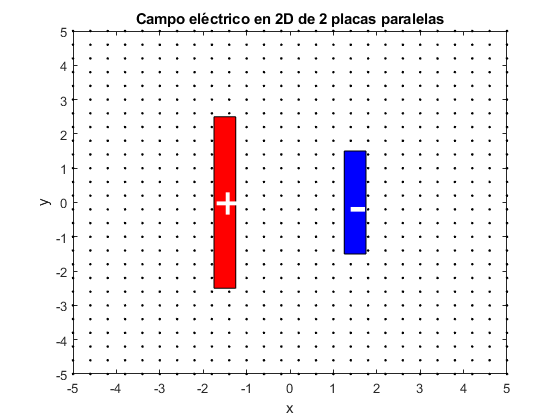

xg = input("\nIngrese el valor de x: ");

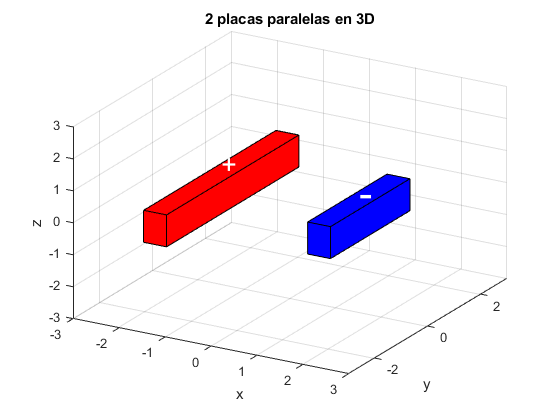

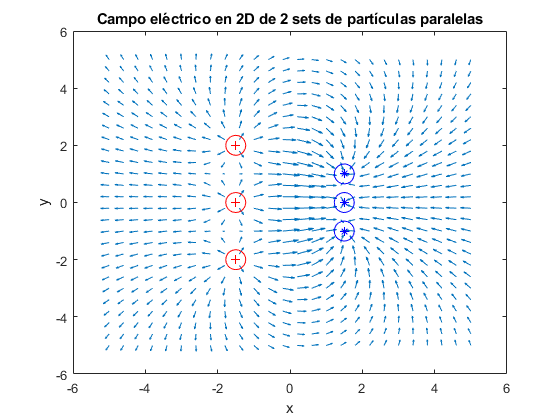

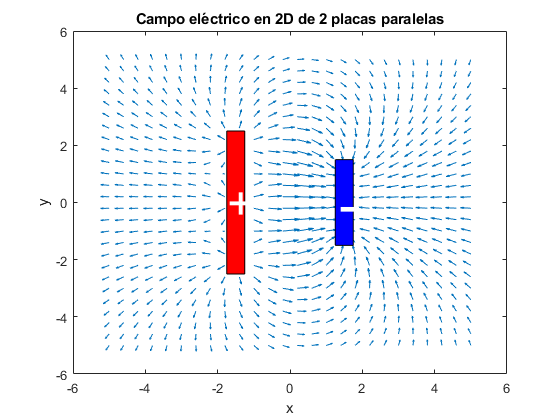

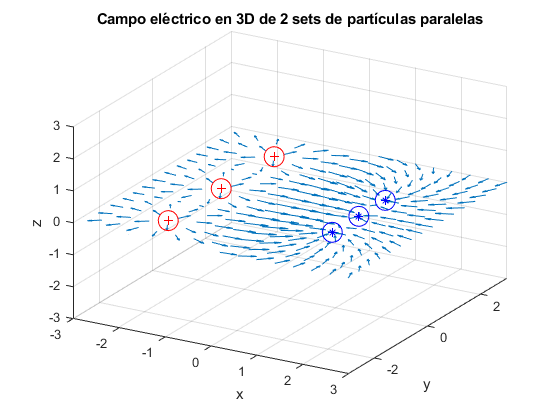

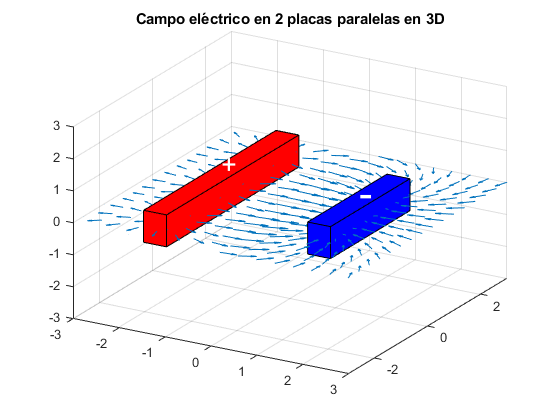

yg = input("\nIngrese el valor de y: ");

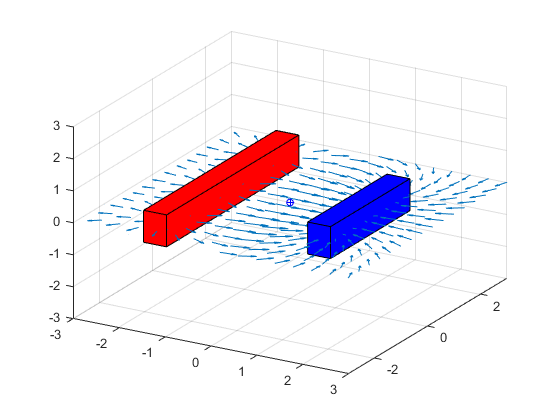

zg = input("\nIngrese el valor de z: ");
d = 7.37e-6;
xgd = xg + d;


r = 1e-19 + (1.1e-19+0)*rand(1,1);
q = -(r);

r2 = 1e-19 + (1.1e-19+0)*rand(1,1);
q2 = r2;


cont = 1;

while cont ~=0
    if yg > dy || yg<-dy || xg > dy2 || xg<-dy2
        nada = input("Coordenadas fuera de rango ..." + ...
"Presione enter para reingresarlas");
        xg = input("\nIngrese el valor de x: ");
        yg = input("\nIngrese el valor de y: ");
        zg = input("\nIngrese el valor de z: ");
        
    else
        cont = 0;
    
    end
end


xg1 = xg - nx;
yg1 = yg - ny;
zg1 = zg-nz;
rg1 = sqrt(xg1^2+yg1^2+zg1^2);    
Exg1 = (k*q*xg1)/rg1^3;
Eyg1 = (k*q*yg1)/rg1^3;
Ezg1 = (k*q*zg1)/rg1^3;

xg2 = xg - nx3;
yg2 = yg - ny3;
zg2 = zg-nz3;
rg2 = sqrt(xg2^2+yg2^2+zg2^2);

Exg2 = (k*q*xg2)/rg2^3;
Eyg2 = (k*q*yg2)/rg2^3;
Ezg2 = (k*q*zg2)/rg2^3;

xg3 = xg - nx5;
yg3 = yg - ny5;
zg3 = zg-nz5;
rg3 = sqrt(xg3^2+yg3^2+zg3^2);

Exg3 = (k*q*xg3)/rg3^3;
Eyg3 = (k*q*yg3)/rg3^3;
Ezg3 = (k*q*zg3)/rg3^3;

Exg = Exg1 + Exg2 + Exg3;
Eyg = Eyg1 + Eyg2 + Eyg3;
Ezg = Ezg1 + Ezg2 + Ezg3;


%Lado derecho
xg4 = xgd - nx2;
yg4 = yg - ny2;
zg4 = zg-nz2;
rg4 = sqrt(xg4^2+yg4^2+zg4^2);

Exg4 = (k*q2*xg4)/rg4^3;
Eyg4 = (k*q2*yg4)/rg4^3;
Ezg4 = (k*q2*zg4)/rg4^3;

xg5 = xgd - nx4;
yg5 = yg - ny4;
zg5 = zg-nz4;
rg5 = sqrt(xg5^2+yg5^2+zg5^2);

Exg5 = (k*q2*xg5)/rg5^3;
Eyg5 = (k*q2*yg5)/rg5^3;
Ezg5 = (k*q2*zg5)/rg5^3;

xg6 = xgd - nx6;
yg6 = yg - ny6;
zg6 = zg-nz6;
rg6 = sqrt(xg5^2+yg5^2+zg5^2);

Exg6 = (k*q2*xg6)/rg6^3;
Eyg6 = (k*q2*yg6)/rg6^3;
Ezg6 = (k*q2*zg6)/rg6^3;


Exgd = Exg4 + Exg5 + Exg6;
Eygd = Eyg4 + Eyg5 + Eyg6;
Ezgd = Ezg4 + Ezg5 + Ezg6;

Eizq = sqrt(Exg^2+Eyg^2+Ezg^2);
Eder = sqrt(abs(Exgd^2 + Eygd^2 + Ezgd^2));



%Si es más de 10% es infectado, si es menor es sano
h4 = quiver3(xx,yy,zz,cx,cy,cz,'autoscalefactor',1);
hold on
plot3(xg, yg, zg, 'b o', 'Markersize', 5);
plot3(xg, yg, zg, 'b +', 'Markersize', 5);

plot3(xgd, yg, zg, 'b o', 'Markersize', 5);
plot3(xgd, yg, zg, 'b +', 'Markersize', 5);

patch('Faces',caras,'Vertices',vertices,'FaceColor','r');
patch('Faces',caras,'Vertices',vertices2,'FaceColor','b');
axis([-3 3 -3 3 -3 3]);
view(30,30); %Establecer la vista de el espacio 3D
hold off

figure

error = (((Eder - Eizq)/Eder)*100);

if error > 10
    disp("Globulo infectado")
else
    disp("Globulo sano")
end

Globulo infectado



disp("Porcentaje de dieferencia: ")

Porcentaje de dieferencia: 


disp(error)

   10.1248




disp("Carga del lado izquierdo")

Carga del lado izquierdo


disp(q)

  -1.8803e-19




disp("Carga del lado derecho")

Carga del lado derecho


disp(q2)

   1.1561e-19

